%%%% Least square fitting 
 A = [2 0; -1 1; 0 2]

A =      2     0
    -1     1
     0     2


 B = [1;0;-1]

B =      1
     0
    -1


 x = A\B

x =     0.3333
   -0.3333



norm(A*x - B) %%% note here we are trying to fit x to minimize this norm value. 

ans = 1.4048

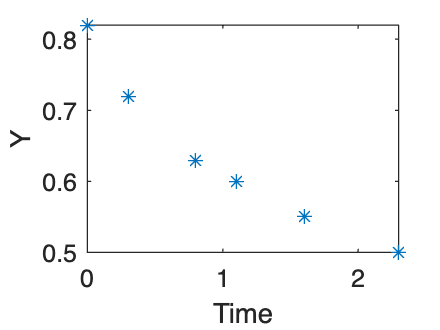



%%% Curve fitting
t = [0 0.3 0.8 1.1 1.6 2.3]';
y = [0.82 0.72 0.63 0.6 0.55 0.5]';

plot(t,y,'*')
xlabel('Time')
ylabel('Y')


%%%% fit y(t) = x1 + x2*e^-t;

E = [ones(size(t)) exp(-t)];

x = E\y  %%%% use back slash dividing.

x =     0.4760
    0.3413



y_fit = x(1) + x(2)*exp(-t)

y_fit =     0.8173
    0.7288
    0.6293
    0.5896
    0.5449
    0.5102


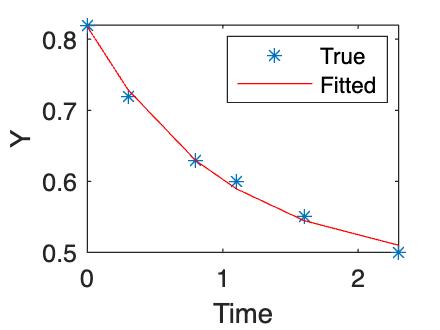


plot(t,y,'*',t,y_fit,'-r')
legend('True','Fitted')
xlabel('Time')
ylabel('Y')



%%%% MATLAB least square curve fitting.


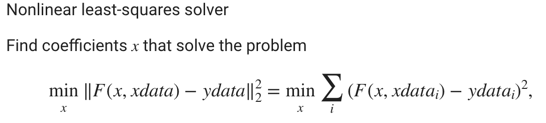

clear x
fun = @(x,t) x(1)+x(2)*exp(-t);
x_lsq = lsqcurvefit(fun,[0.1 0.4],t,y)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x_lsq =     0.4760    0.3413




rng default % for reproducibility
%%% generate a function and use curve fitting to fit the function.
xdata = linspace(0,3);
%%% y = a*exp(b*xdata) + c*xdata^3 + epsilon.;  
a = 0.5; 
b = -2; 
c = 0.05;
ydata = a*exp(b*xdata) + c*randn(size(xdata))

ydata =     0.5269    0.5623    0.3300    0.4600    0.4083    0.3039    0.3259    0.3443    0.4868    0.4283    0.2053    0.4085    0.2779    0.2243    0.2498    0.1912    0.1834    0.2529    0.2384    0.2289    0.1824    0.0797    0.1677    0.2056    0.1412    0.1616    0.1398    0.0822    0.1063    0.0469    0.1256    0.0190    0.0185    0.0272   -0.0835    0.1319    0.0727    0.0154    0.1185   -0.0385    0.0392    0.0296    0.0552    0.0526   -0.0085    0.0312    0.0225    0.0604    0.0819    0.0811


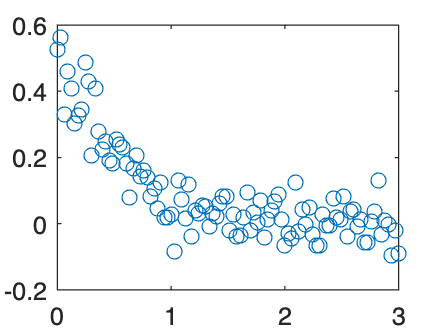

plot(xdata,ydata,'o')


fun = @(x,xdata) x(1)*exp(x(2)*xdata);


lb = [0,-2];
ub = [1,3];

x0 = [0.1,1];
x_fit = lsqcurvefit(fun,x0,xdata,ydata,lb,ub)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x_fit =     0.5303   -1.9212



y_fit = x_fit(1)*exp(x_fit(2)*xdata)

y_fit =     0.5303    0.5003    0.4720    0.4453    0.4201    0.3963    0.3739    0.3528    0.3328    0.3140    0.2962    0.2795    0.2637    0.2488    0.2347    0.2214    0.2089    0.1971    0.1859    0.1754    0.1655    0.1561    0.1473    0.1390    0.1311    0.1237    0.1167    0.1101    0.1039    0.0980    0.0925    0.0872    0.0823    0.0776    0.0733    0.0691    0.0652    0.0615    0.0580    0.0548    0.0517    0.0487    0.0460    0.0434    0.0409    0.0386    0.0364    0.0344    0.0324    0.0306


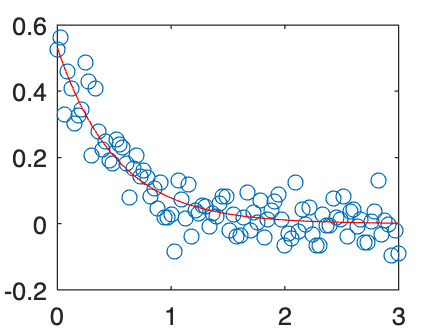


plot(xdata,ydata,'o',xdata,y_fit,'-r')

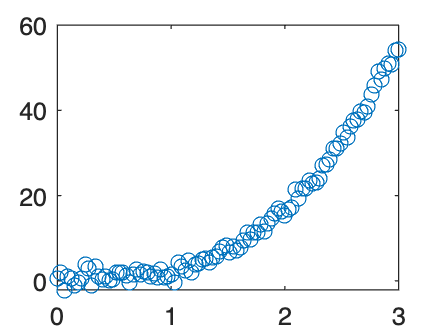




%%%%% In-class exercise
%%% y = a*x^3 - b*sin(x) + c*exp(d*x) + 0.05*randn(size(xdata));
%%% fit for a, b, and c, with initial guess a = 0.1; b = -0.2; c = 1;

rng default % for reproducibility
xdata = linspace(0,3,100);
a = 2; 
b = -0.1; 
c = 0.1;
d = 1;
ydata = a*xdata.^3 - b*sin(xdata) + c*exp(d*xdata) + randn(size(xdata));
plot(xdata,ydata,'o')


fun1 = @(x,xdata) x(1)*exp(x(2)*xdata);
fun2 = @(x,xdata) x(1)*xdata.^3 - x(2)*sin(xdata) + x(3)*exp(x(4)*xdata);


x01 = [0.1,1];
x_fit1 = lsqcurvefit(fun1,x01,xdata,ydata) %%,lb,ub)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x_fit1 =     1.1672    1.3087



x02 = [0.1,1,0.5,0.1];

x_fit2 = lsqcurvefit(fun2,x02,xdata,ydata) %%,lb,ub)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x_fit2 =     1.8961    1.1266    0.8736    0.5615


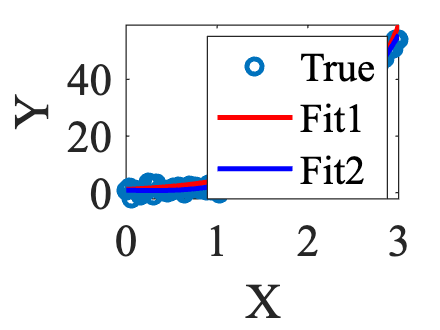


y_fit1 = x_fit1(1)*exp(x_fit1(2)*xdata);
y_fit2 = x_fit2(1)*xdata.^3 - x_fit2(2)*sin(xdata) + x_fit2(3)*exp(x_fit2(4)*xdata);


plot(xdata,ydata,'o',xdata,y_fit1,'-r',xdata,y_fit2,'-b','LineWidth',2)
legend('True','Fit1','Fit2')
set(gca,'FontSize',18)
set(gca,'FontName','Times New Roman')
xlabel('X')
ylabel('Y')



% % % fmin_fit = fminunc(@(x) objFit(x,xdata,ydata),x02)
% % % y_fmin = fmin_fit(1)*xdata.^3 - fmin_fit(2)*sin(xdata) + fmin_fit(3)*exp(fmin_fit(4)*xdata);
% % % 
% % % plot(xdata,ydata,'o',xdata,y_fit1,'-r',xdata,y_fit2,'-b',xdata,y_fmin,'-k','LineWidth',2)
% % % legend('True','Fit1','Fit2','Fmin')
% % % set(gca,'FontSize',18)
% % % set(gca,'FontName','Times New Roman')
% % % xlabel('X')
% % % ylabel('Y')

%%%%% MATLAB Optimization toolbox

Nonlinear programming solver.

Finds the minimum of a problem specified by

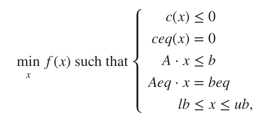

`x = fmincon(fun,x0,A,b,Aeq,beq,lb,ub)`

*b* and *beq* are vectors, *A* and *Aeq* are matrices, *c*(*x*) and *ceq*(*x*) are functions that return vectors, and *f*(*x*) is a function that returns a scalar. *f*(*x*), *c*(*x*), and *ceq*(*x*) can be nonlinear functions.

%%%% No constraints 
%%%% minimize x1^2 - 2*x1*x2 + 4*x2^2
x0 = [-1,2];
[x1,fval] = fminunc(@obj1,x0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x1 = 1.0e-06 *

    0.3486   -0.9089


fval = 4.0599e-12


% % [x,fval]=fminunc('objfun',x0)

x0=[1;1;1];
[x2,fval] = fminunc(@objfununc,x0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x2 =     0.5000
    0.5000
   -0.0000


fval = -0.5000




%%%% example: minimize f(x) = 100*(x2-x1^2)^2 + (1-x1)^2

%%%% with no equality constraints
x0 = [-1,2];
A = [1,2];
b = 1;
fun = @(x)100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
x = fmincon(fun,x0,A,b)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.5022    0.2489



%%%% with both equality and inequality constraints.
x0 = [0.5,0];
A = [1,2];
b = 1;
Aeq = [2,1];
beq = 1;
x = fmincon(fun,x0,A,b,Aeq,beq)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.4149    0.1701




%%%% in-class exercise with bounds
%%%f = 1+ x1/(1+x2) - 3*x1*x2 + x2*(1+x1);
x0 = [0.5, 0.5];
A = [1,2];
b = 3;
Aeq = [2,1];
beq = 1;
lb = [0,0];
ub = [1,2];
x = fmincon(@obj3,x0,A,b,Aeq,beq,lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.3514    0.2972



obj3(x)

ans = 1.3592

function f = obj3(x)
    f = 1+x(1)/(1+x(2)) - 3*x(1)*x(2) + x(2)*(1+x(1));
end

 
function f= obj1(x)
f = x(1)^2 - 2*x(1)*x(2)+4*x(2)^2;
end

function f=objfununc(x)
    f=(x(1)^2+x(2)^2)^2-x(1)^2-x(2)+x(3)^2;
end

function objFit = objFit(x,xdata,ydata)
    fitfunction = x(1)*xdata.^3 - x(2)*sin(xdata) + x(3)*exp(x(4)*xdata);
    objFit = sum(fitfunction - ydata).^2;
end
